## Exercise 2: Several Triangles

Let's consider now four triangles adding a central vertex (as it is shown in the figure below). We can define these polygons by the coordinates of the vertices and the triangles defined by these vertices,


$$$$
v_{1} = (0.0, 0.0),\quad
v_{2} = (1.0, 0.0),\quad
v_{3} = (1.0, 1.0),\quad
v_{4} = (0.0, 1.0),\quad
v_{5} = (0.5, 0.5).
$$$$


Then,

- Decide to which triangle belongs the point $p = (0.8, 0.7)$.

- Assume the temperatures at the vertices are: $T(0,0) = 10^{\mathrm{o}}\mathrm{C}$, $T(1,0) = 20^{\mathrm{o}}\mathrm{C}$,  $T(1,1) = 30^{\mathrm{o}}\mathrm{C}$, $T(0,1) = 40^{\mathrm{o}}\mathrm{C}$, and $T(0.5, 0.5) = 50^{\mathrm{o}}\mathrm{C}$. Compute the interpolated temperature at the given point $p$.

Files required: `baryCoord.m `and `plotTriangleMesh.m`. The last one is packed in the zipped file [additionalFiles.zip](https://numfactory.upc.edu/numfactory/subjects/FEM/Extra/additionalFiles.zip),  which you can download form Toni Susin's[ Numerical Factory.](https://numfactory.upc.edu/blog/2018/09/03/finite-element-introduction-course/)

clearvars
close all

p = [0.8, 0.7];


First we introduce the matrix with the positions of the vertices (the nodes) and the *connectivity *matrix, 


$$$$
\mathrm{nodes} = \left(\begin{array}{cc}
0.0 & 0.0 \\
1.0 & 0.0 \\
1.0 & 1.0 \\
0.0 & 1.0 \\
0.5 & 0.5\end{array}\right),\qquad
\mathrm{elem} =\left(\begin{array}{ccc}
1 & 2 & 5 \\
2 & 3 & 5 \\
3 & 4 & 5 \\
4 & 1 & 5\end{array}\right).
$$$$


nodes = [
    0,0;
    1,0;
    1,1;
    0,1;
    0.5,0.5;
    ];
elem =  [ 
    1, 2, 5;
    2, 3, 5;
    3, 4, 5;
    4, 1, 5
];
numElem = size(elem,1);

temp = 10:10:50; %Temperature at the nodes, according to the global
                 %numeration
                 

Draw the area meshed by triangles and mark the point $p$ at its inside

figure()
plotElements(nodes,elem,1);
hold on
plot(p(1,1),p(1,2),'o','Marker','o','MarkerFaceColor','red',...
    'MarkerEdgeColor','black','MarkerSize',6)
hold off

Find out to which element (i.e., to which triangle) belongs point $p$  and compute the interpolated temperature at that point; according to the formula,


$$$$
T(p) \approx T_{\mathrm{interp}}(p) = \alpha_{1} T_{1} + \alpha_{2} T_{2}  + \alpha_{3} T_{3},$$


where $\alpha_{1}$, $\alpha_{2}$ and $\alpha_{3}$ are the barycentric coordinates of point $p$ w.r.t. the wertices of the triangle it belongs to, and $T_{1}$, $T_{2}$, $T_{3}$ are, respectively, the temperatures at the first, second and third local nodes of this triangle.

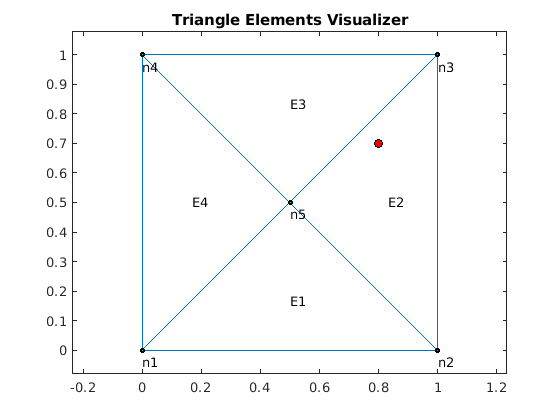

for e=1:numElem
    n1 = elem(e,1);
    n2 = elem(e,2);
    n3 = elem(e,3);
    v1 = nodes(n1,:);
    v2 = nodes(n2,:);
    v3 = nodes(n3,:);
    vertexs = [v1;v2;v3];
    [alphas, isInside] = baryCoord(vertexs, p);

    if isInside >= 1
        nodsElem = [n1,n2,n3];
        interpTemp = alphas(1)*temp(n1) + alphas(2)*temp(n2) + alphas(3)* temp(n3);
        fprintf('-----------------------------------------------------\n')
        fprintf('Fancy output, don''t try this at the exams!!\n')
        fprintf('-----------------------------------------------------\n')
        fprintf('Point: p=(%f,%f)\n',p);
        fprintf('Elem: %d\n',e);
        fprintf('Nodes: %d,%d,%d\n',nodsElem);
        fprintf('%20s\n','Vertexs Coords.')
        fprintf('%7s%11s\n','X','Y')
        fprintf('%12.5e%12.5e\n',vertexs')
        fprintf('Interpolated Temp.: T(%f,%f) = %.4f%cC\n',p,interpTemp,char(176));
        fprintf('-----------------------------------------------------\n')
        % A faster vay to print out the results
        fprintf('A faster way to show the results...\n')
        format short e
        p
        e
        nodsElem
        vertexs
        interpTemp        
        break;
    end
end

-----------------------------------------------------


Fancy output, don't try this at the exams!!


-----------------------------------------------------


Point: p=(0.800000,0.700000)


Elem: 2


Nodes: 2,3,5


     Vertexs Coords.


      X          Y


 1.00000e+00 0.00000e+00
 1.00000e+00 1.00000e+00
 5.00000e-01 5.00000e-01


Interpolated Temp.: T(0.800000,0.700000) = 37.0000°C


-----------------------------------------------------


A faster way to show the results...


p =    8.0000e-01   7.0000e-01


e =      2


nodsElem =      2     3     5


vertexs =    1.0000e+00            0
   1.0000e+00   1.0000e+00
   5.0000e-01   5.0000e-01


interpTemp =     37
